% Linear Regression w/ grad descent 
% goal: choose important features, and find/ minimize beta coefficients
% once we find our coeffs, our model is ready to predict using test data
%   and LA data



% load the data
fulltable = readtable('day.csv');
% 2nd column (dteday) can be removed, this column gives us 
% a date that increments by one, we can use the instant column
% as an indicator of days passed. the dteday column is not needed.
% instant gives us # of days since program inception

% eliminate feats, then check for correlation and lasso reg
fulltable(:,"dteday") = []; % eliminate date
fulltable(:,"instant") = [];    % eliminate instant
fulltable(:,"registered") = []; % eliminate registered
fulltable(:,"casual") = []; % eliminate casual
fulltable(:,"weekday") = []; % eliminate weekday
fulltable(:,"hum") = []; % eliminate humidity
fulltable(:,"holiday") = []; % eliminate holiday


trainingDay1 = table2array(fulltable);

[testDay, trainingDay] = splitTestTraining(trainingDay1,0.2); % the returned sets also have the labels 


% --------
% FEATURE SELECTION

% are any features correlated? if so, eliminate
 trainingDayUpd = correlation(trainingDay); % this gives us training set with fewer columns

Eliminated any correlated features.


 trainingDayUpd2 = trainingDayUpd;
% set up data for cross validation to find lambdas for regularization
% pick good lambda
% use lasso to eliminate irrelevant features. 
% partition the data in 10 sections 
c = cvpartition(size(trainingDayUpd,1),'KFold',10)

c = K-fold cross validation partition
   NumObservations: 585
       NumTestSets: 10
         TrainSize: 527  526  526  526  526  526  527  527  527  527
          TestSize: 58  59  59  59  59  59  58  58  58  58

%err = zeros(CVO.NumTestSets,1);

% looping through the 10 folds for cross val
setOfLambdas = [];
for i = 1:c.NumTestSets
    trIdx = c.training(i);   % this is data for training (9/10 folds)
    teIdx = c.test(i);       % this is data for validation (1/10 folds)
  
    [B,FitInfo] = lasso(trainingDayUpd(trIdx,1:end-1), trainingDayUpd(trIdx,end));
    avgLambda = sum(FitInfo.Lambda)/100;
    setOfLambdas = [setOfLambdas, avgLambda];
   
    
end


% look at lasso results: 
 [B2,FitInfo2] = lasso(trainingDayUpd(:,1:end-1), trainingDayUpd(:,end), 'Lambda', 0.712)

B2 = 	1.0e+03 *

    0.4688
    2.0827
   -0.0360
    0.2243
   -0.7163
    2.6327
    2.8904
   -2.2418


FitInfo2 = struct with fields:
         Intercept: 1.1285e+03
            Lambda: 0.7120
             Alpha: 1
                DF: 8
               MSE: 7.4777e+05
    PredictorNames: {}


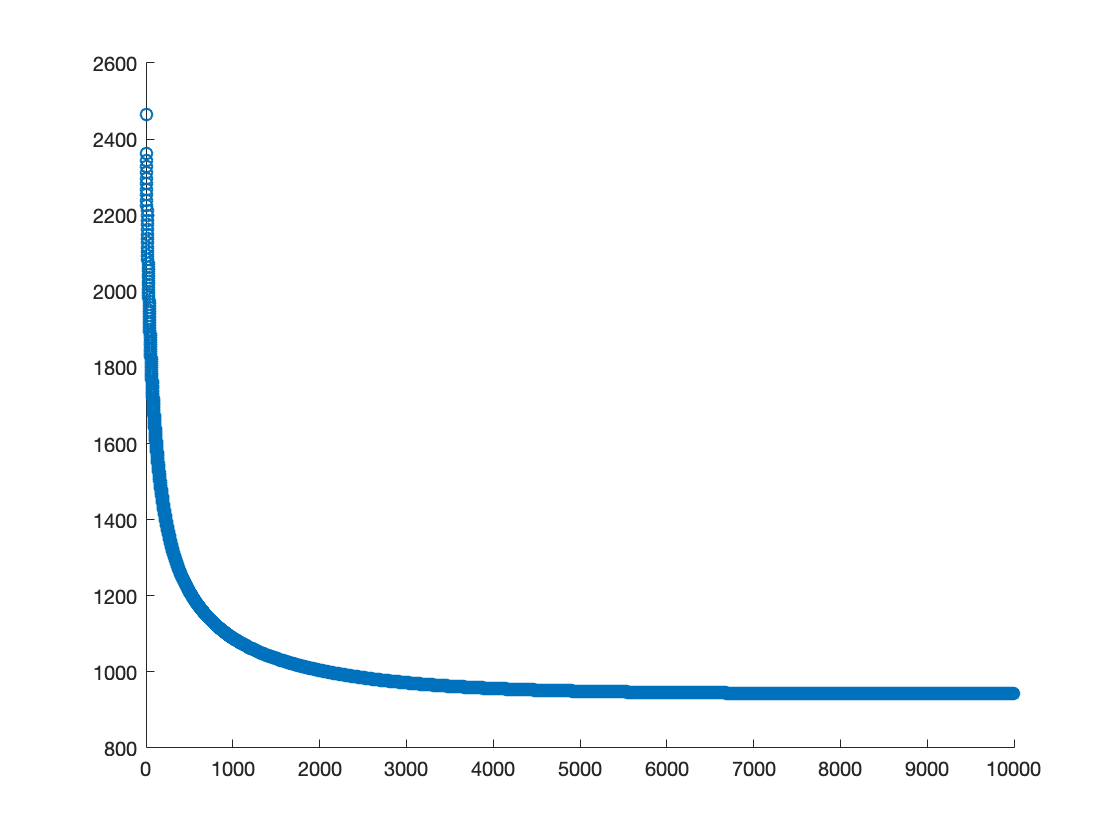


% this will give us some randomization
% though it is still advisable to randomize the data before hand


% --------
% LIN REGRESSION WITH GRAD DESCENT
% feature selectin reduced the number of feats i.e. coeffs
% now try to minimize loss for lin reg via gradient descent
% loss function
% we ended up with 6 features: perform gradient descent using these 6
% features. left over features are shwon below.



fulltable = readtable('day.csv');
% 2nd column (dteday) can be removed, this column gives us 
% a date that increments by one, we can use the instant column
% as an indicator of days passed. the dteday column is not needed.
% instant gives us # of days since program inception
fulltable(:,"dteday") = [];
trainingDay1 = table2array(fulltable);

[testDay, trainingDay] = splitTestTraining(trainingDay1,0); 



% LIN REGRESSION WITH GRAD DESCENT
% feature selectin reduced the number of feats i.e. coeffs
% now try to minimize loss for lin reg via gradient descent
% loss function
% we ended up with 6 features: perform gradient descent using these 6
% features. left over features are shwon below.



% initialize betas to 0
beta0 = 0;  % intercept
beta1 = 0;  % feat 1 
beta2 = 0;  % feat 2
beta3 = 0;  % feat 3 
beta4 = 0;  % feat 4 
beta5 = 0;  % feat 5 
beta6 = 0;  % feat 6 

% learning rate
L = 0.01;
epochs = 10000;
N = size(trainingDay ,1);
MSE = [];
iterations = [];
    x1 = trainingDay(:,3);
    x2 = trainingDay(:,4);
    x3 = trainingDay(:,7);
    x4 = trainingDay(:,8);   
    x5 = trainingDay(:,10);
    x6 = trainingDay(:,12);
    Y = trainingDay(:,end);
    

    N = size(x4,1);
       betas = [beta1,beta2,beta3,beta4,beta5,beta6];
       allbetas = [];
       features = [x1, x2, x3, x4, x5, x6];
    for i = 1:epochs
         
            
            yhats = betas.*features;
            yhats2 = sum(yhats, 2) + beta0;
           
        
        
           
    beta0_der =  (-2/N) * sum(Y-yhats2,1);
    beta1_der =  (-2/N) * sum(x1.*(Y-yhats2),1);
    beta2_der = (-2/N) * sum(x2.*(Y-yhats2),1);
    beta3_der = (-2/N) * sum(x3.*(Y-yhats2),1);
    beta4_der = (-2/N) * sum(x4.*(Y-yhats2),1);
    beta5_der = (-2/N) * sum(x5.*(Y-yhats2),1);
    beta6_der = (-2/N) * sum(x6.*(Y-yhats2),1);

   
    % update our coefficients using derivatives, learning rate, and current
    % betas
   
    beta0 = beta0 - (L*beta0_der);
    beta1 = beta1 - (L*beta1_der);
    beta2 = beta2 - (L*beta2_der);
    beta3 = beta3 - (L*beta3_der);
    beta4 = beta4 - (L*beta4_der);
    beta5 = beta5 - (L*beta5_der);
    beta6 = beta6 - (L*beta6_der);
     
    betas(1) = beta1;
    betas(2) = beta2;
    betas(3) = beta3;
    betas(4) = beta4;
    betas(5) = beta5;
     betas(6) = beta6;
allbetas = [allbetas ;betas, beta0 ];
    end 
    allRSMEs = [];
    % calculate our error
  for k=1:size(allbetas,1)  
        prediction = sum(allbetas(k, 1:end-1).*features(:, 1:end),2) + allbetas(k, end);
        residuals = Y-prediction;
        mse = mean(residuals.^2);
        rmse = sqrt(mse);
        
        allRSMEs = [allRSMEs, rmse];

  end

  
  
  
  % plot RMSE over iterations in grad descent-- see if converged 
  scatter(1:size(allbetas,1), allRSMEs)



% predict using our betas

% predict using LA-data
LAPrediction =  beta0 + beta1*0 + beta2*1 + beta3*0 + beta4*0.36 + beta5*2+ beta6*0.30;

LAPrediction = 1.3009e+04